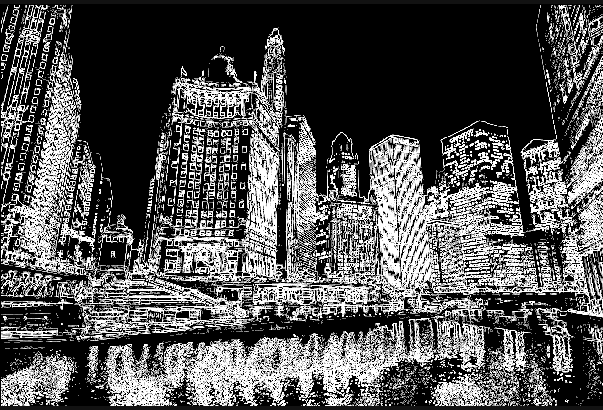

clear
rgb_img = imread("city.jpg");

%rgb to grey scale 
grey = gray_scale(rgb_img);
[height, width] = size(grey);


%inputs for RTL sim
rstn_i = 1; %reset active low
grey_pixle_i = grey(1,1); %grey pixel input from the RBG to grey scale module
x_i = 1; %current pixel x position
y_i = 1; %current pixel y position
eol_i = 0; %end of the line signal
sof_i = 0; % start of the new video signal


%output for RTL sim
grad_mag_o = 0; % gradient maginitude for pixel
pixel_valid_o = 0;
eol_o = 0; % end of the line signal
sof_o = 0; % start of the new video signal

% ----------- interal signals ----------------- %
line_delay0 = zeros(1, width);
line_delay1 = zeros(1, width);
tap0 = 0;
tap1 = 0; 

window = zeros(3,3); %3x3 slidng window

%constants
horiz_kernel = [1, 0, -1; % horizontal kernal
               2, 0, -2;
               1, 0, -1];

vert_kernel = [1,  2,  1; % vertical kernel
               0,  0,  0;
              -1, -2, -1];

for y_i = 1:height
    for x_i = 1:width
        grey_pixle_i = grey(y_i, x_i);

        %read, then write for BRAM access pattern
        tap0 = line_delay0(1, x_i);
        line_delay0(1, x_i) = grey_pixle_i;

        tap1 = line_delay1(1, x_i);
        line_delay1(1, x_i) = tap0;

        %update sliding window shift register
        window(1,1) = window(1,2);
        window(1,2) = window(1,3);
        window(1,3) = tap1;

        window(2,1) = window(2,2);
        window(2,2) = window(2,3);
        window(2,3) = tap0;
        
        window(3,1) = window(3,2);
        window(3,2) = window(3,3);
        window(3,3) = grey_pixle_i;
        
        %convole the window with kernel
        if(x_i >= 3 && y_i >= 3)
            gx = sum(sum(window .* horiz_kernel));
            gy = sum(sum(window .* vert_kernel));

            grad_mag_o = abs(gx) + abs(gy);
            
            if(grad_mag_o < 100)
                grad_mag_o = 0;
            end
            %update final result
            edge(y_i, x_i) = uint8(min(grad_mag_o, 255));
        else
            %send zeros for pixel 
            edge(y_i, x_i) = uint8(0);
        end       
    end 
end  


imshow(edge)

[result_height, result_width] = size(edge)

result_height = 1280

result_width = 1920


function gray_img = gray_scale(rgb_img)
    red_channel = double(rgb_img(:,:,1));
    green_channel = double(rgb_img(:,:,2));
    blue_channel = double(rgb_img(:,:,3));
    gray_img = uint8(0.2989 * red_channel + 0.5870 * green_channel + 0.1140 * blue_channel);
end

clear